# A comparison of open-loop and closed-loop control through a case study

The main purpose of this file is to explore the importance of feedback, that is, why is feedback so important? If we could model the world perfectly, then it is possible to define explicitly what controls are needed to produce a desired output, and indeed in some industrial scenarios that is exactly what is done; uncertainty is removed by specifying very high quality components and huge amounts of testing. Of course that is not financially viable for most scenarios. Feedback is used to counteract the uncertainty that arises due to lower quality components, wear and tear, external factors and more. This app seeks to illustrate these issues through a simple case study.

**NOTE**: When opening the file, the first simulation might take 30 seconds as Simulink needs to be opened.

This live script needs the control toolbox and simulink.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Introduction

- System behaviour and control

-  Introducing an authentic scenario

- Using the app interface

- Appendix: Subfunction to find the switch times for bang bang control

## 1. Introduction

### 1.1 Open and closed-loop control

This resource assumes that the users already have some familiarity with the fundamental concepts of behaviour and performance (e.g. `transferfunctions_and_behaviours, behaviours.mlapp, tanklevelbehaviour.mlapp, effects_of_negative_feedback, ` etc.).  From this it will be evident that behaviours depend heavily on:

- System parameters and construction.

- External factors and disturbances.

A manufacturer will need to deliver a consistent product irrespective of the factors that may cause deviations. There are two simple ways of ensuring this.

- Use very high quality materials and components which, in effect, deliver 100% reproduceability. Alongside these, do extensive testing to determine what choice of inputs deliver the required outputs. In this case the system is open-loop and we assume the product will be satisfactory.

- Introducing monitoring and adjustment, that is, measure the core characteristics of the product as it is produced and make small continuous changes to the system inputs to ensure these characteristics meet the requirements; in effect this means feedback as in Figure 1.

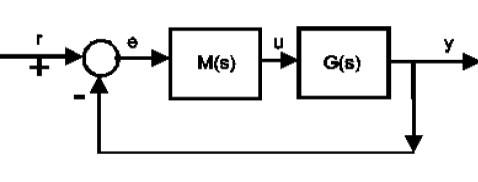

**Figure 1**: *Example of a simple feedback loop for system G(s) and compensator M(s)*

This resource will compare the two scenarios and seek to demonstrate why, in the vast majority of cases, the use of feedback is the preferred option.

### 1.2. Robot arm delivery system

The case study for this resource will be a simple robot arm which moves items from one tray to another tray.  The robot arm is given instructions on which tray to collect from and which tray to deliver to. In order to be effective, the position of the robot arm and its gripper must be very accurate; poor positioning could lead to the gripper failing to grasp the required item and/or the item being placed in the incorrect position. Any failure could lead to component breakages or a pause in the process operation while everything is tidied up and reset. For simplicity of illustration this example will assume there are 4 collection/delivery positions.

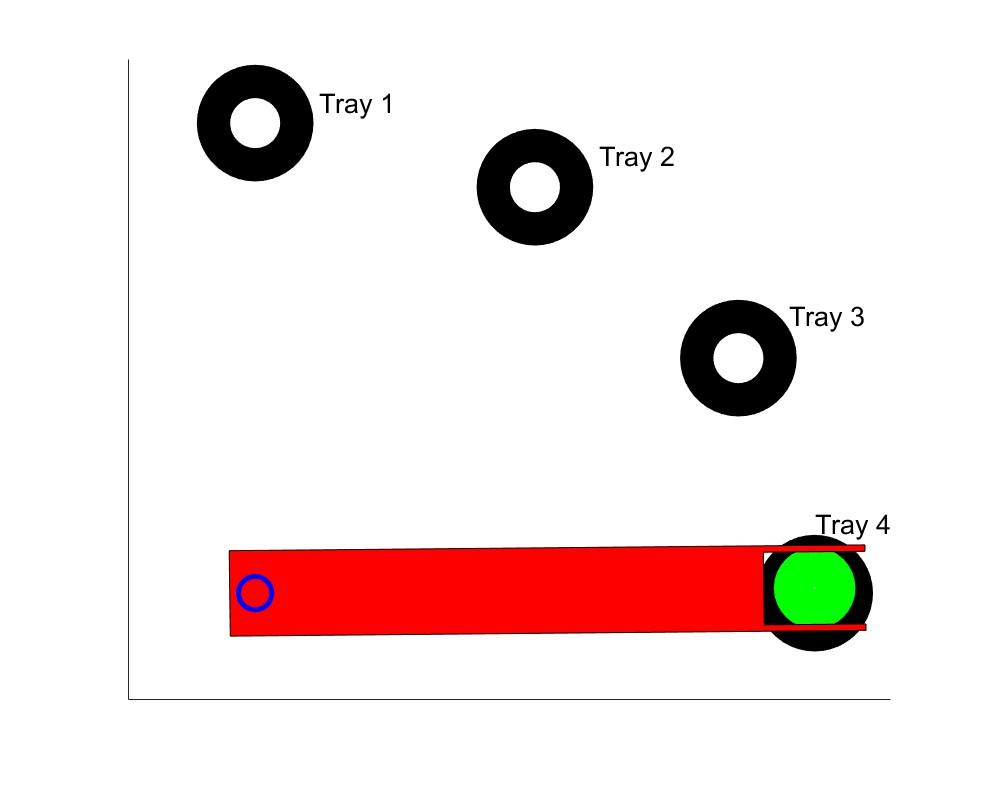

**Figure 2**: *Representation of the robot arm delivery system*

We will assume that the robot arm can be modelled as a simple inertia moved by a DC motor and thus the angular position $\theta$ of the gripper can be captured by a model of the form:

$\theta =\frac{K}{s\left(T\;s+1\right)}U$   where *U* is a voltage input to the servo. For simplicitly of illustration this resource will use *K=1*.

In practice the inertia varies when the robot arm is carrying a load so different models are needed to represent the different loading scenarios.

- Unloaded:   *T=1*

- Item 1:        *T=2*;

- Item 2:        *T=2.5*

The delivery positions or trays correspond to precise angles: $\theta =0,30,60,90\;\textrm{degrees}\ldotp$

### 1.3. Uncertainty in the process

While it is possible in principle to model a process precisely, in practice a number of factors can cause that model to be inaccurate.

- Due to friction (poor maintenance) and wear and tear, the system parameters *K,T* may slowly drift. We may expect *K* to gradually reduce and *T* to gradually increase.

- The loads may not weigh precisely what they are expected to and there is some variance on these. For this simulation, we will assume this is captured by a small variance around the expected value of *T*.

- Other external factors such as temperature and humidity may have small impact on behaviour; for now this is ignored.

- The voltage delivery system may be subject to small timing errors and delays as well as delivering a voltage which is not exactly correct (for example the voltage in the local parts of an electrical grid is never precisely what is desired and can differ by 5-10%).

**Remark**: Smart readers may realise that stepper motors are a sensible proposal for this scenario, but the purpose of this resource is to expose issues with open-loop control in a simple manner, not to propose the best solution for the context.

## 2 System behaviour and control

This section considers how the robot arm might be moved but does not consider the action of the gripper which is a separate process. There are two different scenarios considered: i) open-loop  and ii) closed-loop.

### 2.1 Open-loop minimum time control

In this scenario the engineer uses the model to determine a control signal which will drive the system from one position to another position. For simplicity assume a voltage signal with the following shape (Figure 3). In essence the step up in voltage makes the robot arm accelerate and move. The reverse in voltage brings the robot arm back to a zero velocity. The timings are chosen to ensure the overall movement is the desired one, ideally without any overshoot. As a bang-bang method, this will be minimum time, assuming the voltages used are the maximum and minimum.

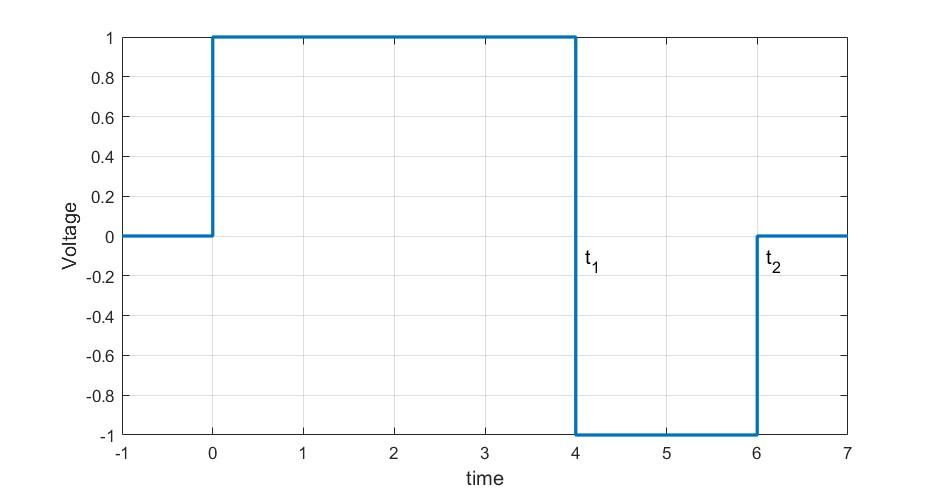

**Figure 3**: *Structure of the required input voltage*

The engineer has a number of parameters to play with, but most notably: the times $t_{1,\;} t_2$ at which the voltage is changed. For simplicitly within this resource:

- assume that the peak max/min voltage is fixed at 1 as this is easier to deliver reliably. [In practice values will differ]

This means that there is only a two parameters to choose, that is the times $t_2 ,\;t_1$. The angle moved will depend precisely on those.  Assuming a perfect model (that is high quality components) this number can be determined analytically as shown in the following developments.

### 2.2 Derviation of the switching times assume a perfect model

#### 2.2.1 First consider the behaviour between 0 and $t_1$ with a constant input


$$\begin{array}{l}
\theta \left(s\right)=\frac{1}{s^2 \left(T\;s+1\right)}=\frac{a}{s^2 }+\frac{b}{s}+\frac{c}{T\;s+1}=\frac{1}{s^2 }+\frac{-T}{s}+\frac{T}{s+\frac{1}{T}}\;\;\;\;\Rightarrow \;\theta \left(t\right)=t-T\left(1-e^{-\frac{t}{T}} \right);\\
w\left(s\right)=\frac{1}{s\left(T\;s+1\right)}=\frac{1}{s}-\frac{1}{s+\frac{1}{T}}\;\;\;\;\Rightarrow w\left(t\right)=\left(1-e^{-\frac{t}{T}} \right)\\
\;\textrm{In}\;\textrm{summary}\;\textrm{the}\;\textrm{angle}\;\textrm{and}\;\textrm{angular}\;\textrm{frequency}\;\textrm{are}:\;\theta \left(t_1 \right)=t_1 -T\left(1-e^{-\frac{t_1 }{T}} \right);\;\;w\left(t_1 \right)=\left(1-e^{-\frac{t_1 }{T}} \right)
\end{array}$$


#### 2.2.2 Consider the slow down phase between $t_1$ and $t_2$ (terminal velocity is required to be zero).

For simplicity, use deviation variables and consider only the change in angle.

$\delta \theta \left(s\right)=\frac{-1+T\;s\;w\left(t_1 \right)}{s^2 \left(T\;s+1\right)}=$$\left(\frac{1}{s^2 }+\frac{-T}{s}+\frac{T}{s+\frac{1}{T}}\right)\left(-1\right)$+$\frac{T\;w\left(t_1 \right)}{s\left(T\;s+1\right)}$


$$\;\delta \theta \left(t_2 \right)=\left\lbrack t_2 -t_1 -T\left(1-e^{-\frac{t_2 -t_1 }{T}} \right)\right\rbrack \left(-1\right)+T\left(1-e^{-\frac{t_2 -t_1 }{T}} \right)w\left(t_1 \right)$$


Next ensure the terminal velocity is zero at $t_2$:


$$w\left(s\right)=\frac{-1+s\;T\;w\left(t_1 \right)}{s\left(T\;s+1\right)}\;\;\;\Rightarrow w\left(t_2 \right)=-\left(1-e^{-\frac{t_2 -t_1 }{T}} \right)+w\left(t_1 \right)e^{-\frac{t_2 -t_1 }{T}} =0$$


Hence: $e^{-\frac{t_2 -t_1 }{T}} =\frac{1}{1+w\left(t_1 \right)}\;\;\;\Rightarrow \;t_2 -t_1 =T\;\log \left(1+w\left(t_1 \right)\right)$.   That is, the time $\;t_2$ is dependent on $\;t_1$ and thus not a free parameter.

#### 2.2.3 Summary of angle dependence on $t_1$

The total angle change is given by the following formula:


$$\;\delta \theta =\theta \left(t_1 \right)+\delta \theta \left(t_2 \right)=t_1 -T\left(1-e^{-\frac{t_1 }{T}} \right)+\left\lbrack t_2 -t_1 -T\left(1-e^{-\frac{t_2 -t_1 }{T}} \right)\right\rbrack \left(-1\right)+T\left(1-e^{-\frac{t_2 -t_1 }{T}} \right)w\left(t_1 \right)=\vartheta_d ;\;t>t_2$$


Let: $\alpha =e^{-\frac{t_1 }{T}} ;\;\;\beta =e^{-\frac{t_2 -t_1 }{T}} ;\gamma =t_2 -t_1$, so the two requirements are summarised as:


$$\;\vartheta_d =t_1 -T\left(1-\alpha \right)-\left\lbrack t_2 -t_1 -T\left(1-\beta \right)\right\rbrack +T\left(1-\beta \right)\left(1-\alpha \right);\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{AND}\;\;\;\;\;\;\;\;\;\;\;t_2 -t_1 =T\;\log \left(1+w\left(t_1 \right)\right)\;$$


We can use a numerical method to explore the change in $\vartheta_d$ as $t_1$ changes and thus find the required values of $t_1$ and $t_2$ for a given angle change.

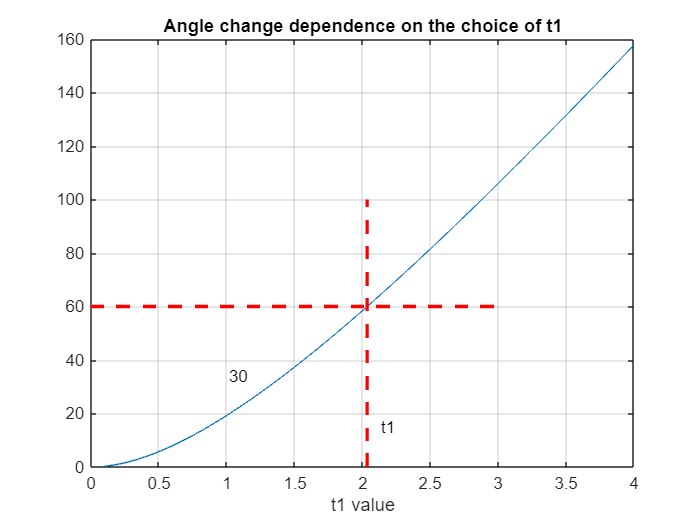

% find and plot angle dependence on time
endtime =4;
target=60;
load =2;
t1=linspace(0.1,endtime,1001);t2=[];
T=load;
for k=1:length(t1);   
        alpha =exp(-t1(k)/load);
        w = 1-alpha;
        t2(k) = load*log(1+w);  % in fact t2-t1
        beta = exp(-t2(k)/load);
        gamma = t2(k);
        delta(k)=t1(k)-load*(1-alpha)-(gamma - load*(1-beta)) +load*(1-beta)*(1-alpha);   
end
figure
plot(t1,delta*180/pi);grid; hold on
title('Angle change dependence on the choice of t1')
xlabel('t1 value')

% Find times giving a 30 degree movement using a subfunction
[t1s,t2s] = findtimes(load,target,endtime);

plot([t1s,t1s],[0 ,100],'r--','LineWidth',2); text(t1s*1.05,15,'t1')
plot([0,t1s*1.5],[target ,target],'r--','LineWidth',2); text(t1s/2,34,'30')
hold off

Hence, it is clear that the movement is linked simply to the time $t_1$assuming $t_2$ is a function of $t_1$. Thus one can choose $t_1$ directly.

#### **2.2.4 Illustration of behaviour**

The expected behaviour with open-loop control is illustrated below (for a target move of 30 degrees). The values for $t_1$, $t_2$ are computed above. Readers will note a small offset as the computations are numerical and only done to a limited accuracy.

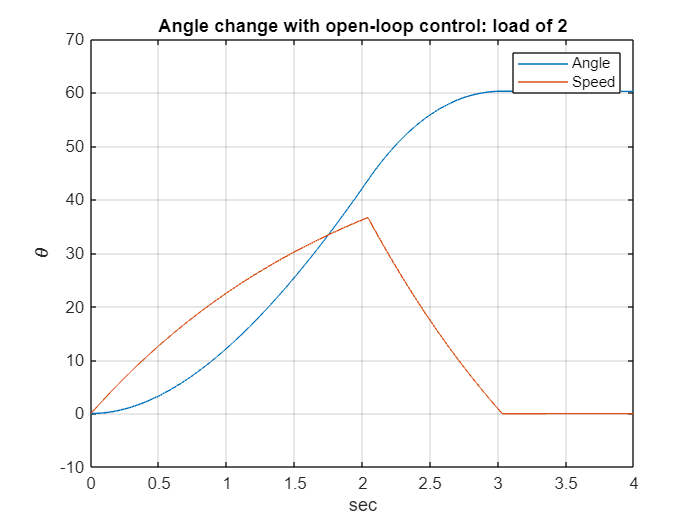

G=tf(1,[load 1 0]);
G2=tf(1,[load 1]);
tt = linspace(0,4,401);
u=[ones(1,401)];
ufalse =le(tt,t1s);
ufalse2 =le(tt,t2s);
u1=-u.*ufalse2;
u2 =u.*ufalse;
uu=2*u2+u1;

[y]=lsim(G,uu,tt);
yy=lsim(G2,uu,tt);
plot(tt,y*180/pi,tt,yy*180/pi); title(['Angle change with open-loop control: load of ',num2str(load)])
legend('Angle','Speed')
xlabel('sec')
ylabel('\theta')
grid

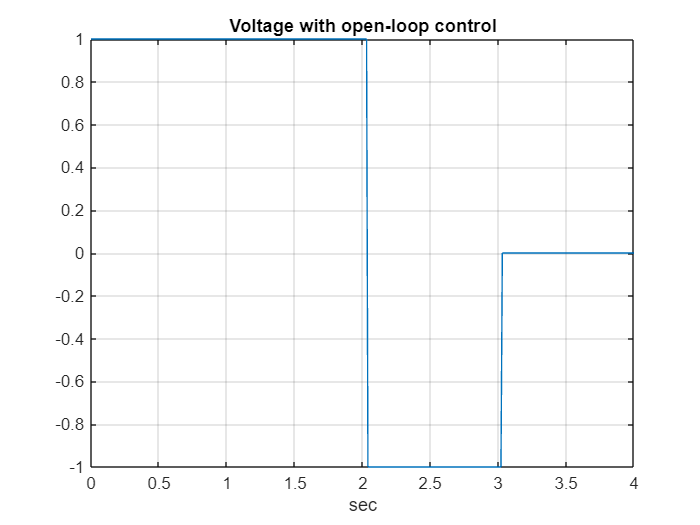

plot(tt,uu); grid
title('Voltage with open-loop control')
xlabel('sec')

### 2.3. Open loop maximum speed control

An alternative and perhaps simpler open-loop design is to assume that the arm has a maximum speed and travels a good distance at that speed. Hence, the input signal accelerates the arm to this maximum angular velocity, maintains this for a while and then decelerates. Such a signal is shown next where the time for the positive voltages matches the time for the negative voltage so that the final velocity is zero.

disp('Section 2.3');

Section 2.3


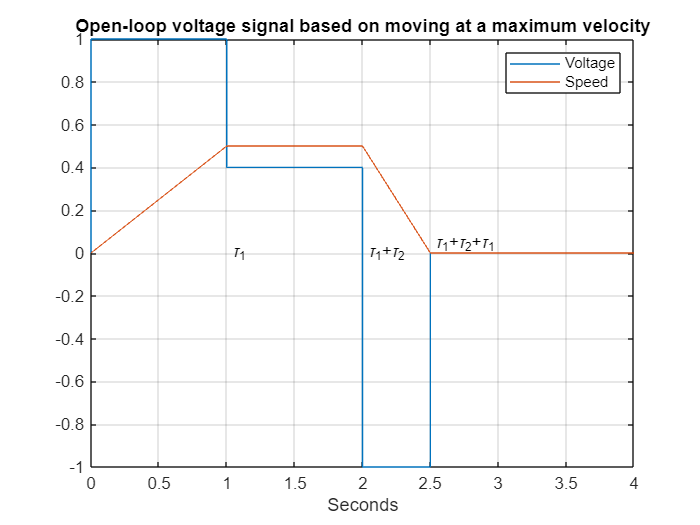

t1=0;t2=1;t3=2;t4=2.5;t5=4;
t=[0,t1,t1,t2,t2,t3,t3,t4,t4,t5];
u=[0 0 1 1 0.4 0.4 -1 -1 0 0];
plot(t,u); grid
title('Open-loop voltage signal based on moving at a maximum velocity'); hold on
plot([0,t2,t3,t4,t5],[0,0.5,0.5,0,0])
legend('Voltage','Speed')
text(t2+0.03,0,'\tau_1')
text(t3+0.03,0,'\tau_1+\tau_2')
text(t4+0.03,0.04,'\tau_1+\tau_2+\tau_1')
xlabel('Seconds');
hold off

The distance moved and velocity can be computed using similar equations to the previous section, but these are now somewhat simpler. We have 2 core variables:

- Time $\tau_1$for which which voltage is held initially to get to the maximum velocity.

- Time $\tau_2$ for which voltage is held at a specified value to ensure the arm moves at constant maximum speed.

- The time $\tau_3$ for which the voltage is negative to bring velocity back to zero.

Given a maximum speed $w_{\max }$ is decreed, we can work out the time $\tau_1$ to reach that speed.


$$w\left(\tau_1 \right)=\left(1-e^{-\frac{\tau_1 }{T}} \right)\Longrightarrow \;\tau_1 =-T\;\log \left(1-w_{\max } \right)$$


The slow down phase is slightly different as now the voltage is negative and there is an initial velocity.

$w\left(\tau_3 \right)=-\left(1-e^{-\frac{\tau_3 }{T}} \right)+w_{\max } e^{-\frac{\tau_3 }{T}} =0\Longrightarrow \;\tau_3 =T\;\log \left(1+w_{\max } \right)$  and $e^{-\frac{\tau_3 }{T}} =\frac{1}{1+w_{\max } }$

The angle moved in the first two phases is solved from:


$$\begin{array}{l}
\theta \left(\tau_1 \right)=\tau_1 -T\left(1-e^{-\frac{\tau_1 }{T}} \right);\;\;\;w\left(\tau_1 \right)=\left(1-e^{-\frac{\tau_1 }{T}} \right)=w_{\max } ;\;\;\;\;\;\;\;\;\;\;\theta \left(\tau_1 \right)=\tau_1 -Tw_{\max } \;\\
\theta \left(\tau_1 +\tau_2 \right)=\tau_1 -Tw_{\max } +\tau_2 w_{\max } \\
\;
\end{array}$$


The slow down phase is also similar to the previous section so that:

$\;\delta \theta \left(\tau_3 \right)=\left\lbrack \tau_3 -T\left(1-e^{-\frac{\tau_3 }{T}} \right)\right\rbrack \left(-1\right)+T\left(1-e^{-\frac{\tau_3 }{T}} \right)w_{\max }$  or $\delta \theta \left(\tau_3 \right)=\left\lbrack \tau_3 -T\left(1-\frac{1}{1+w_{\max } }\right)\right\rbrack \left(-1\right)+T\left(1-\frac{1}{1+w_{\max } }\right)w_{\max }$

Hence: $\delta \theta \left(\tau_3 \right)=\left\lbrack {-\tau }_3 +T\left(1-\frac{1}{1+w_{\max } }\right)\left(1+w_{\max } \right)\right\rbrack =\left\lbrack {-\tau }_3 +Tw_{\max } \right\rbrack$


$$\theta \left(\tau_1 +\tau_2 +\tau_1 \right)=\tau_1 +\tau_2 w_{\max } {-\tau }_3 \;$$


In summary, the required time at steady velocity can be solved very easily as: $\tau_2 =\frac{\delta \theta +\tau_3 -\tau_1 }{w_{\max } }$

wmax=0.5;   % rad/s
G=tf(1,[load 1 0]); T=load;
G2=tf(1,[load 1]);
ttnew = linspace(0,10,1001);
u=[ones(1,1001)];
disp('Switching times')

Switching times


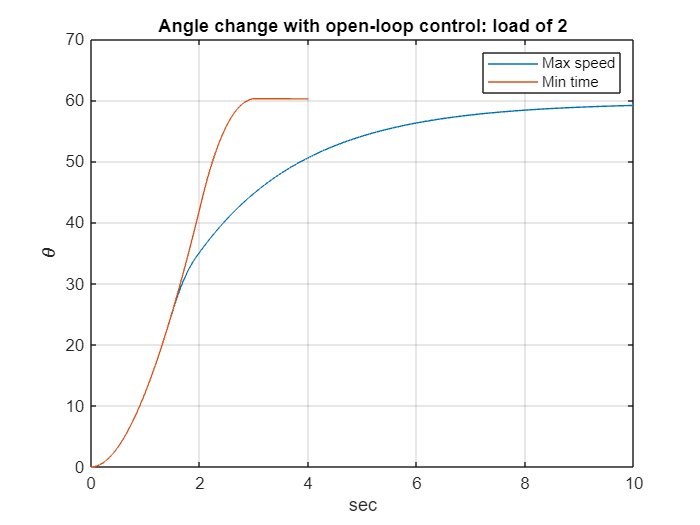

tau1 = -T*log(1-wmax);
tau3 = log(1+wmax);
tau2 = ((pi/3)+tau3 - tau1)/wmax;

ufalse =le(ttnew,tau1);
ufalse2 =ge(ttnew,tau1+tau2);
ufalse3 =ge(ttnew,tau1+tau2+tau3);
uc1 = ge(ttnew,tau1).*u;
uc2 = ge(ttnew,tau1+tau2).*u;
u2=-u.*ufalse2;
u1 =u.*ufalse;
u3=u.*ufalse3;
uunew=u2+u1+u3 +(uc1-uc2)*wmax;


[ynew]=lsim(G,uunew,ttnew);   % angle
yynew=lsim(G2,uunew,ttnew);   % velocity
plot(ttnew,ynew*180/pi,tt,y*180/pi); title(['Angle change with open-loop control: load of ',num2str(load)])
xlabel('sec')
ylabel('\theta')
legend('Max speed','Min time')
grid

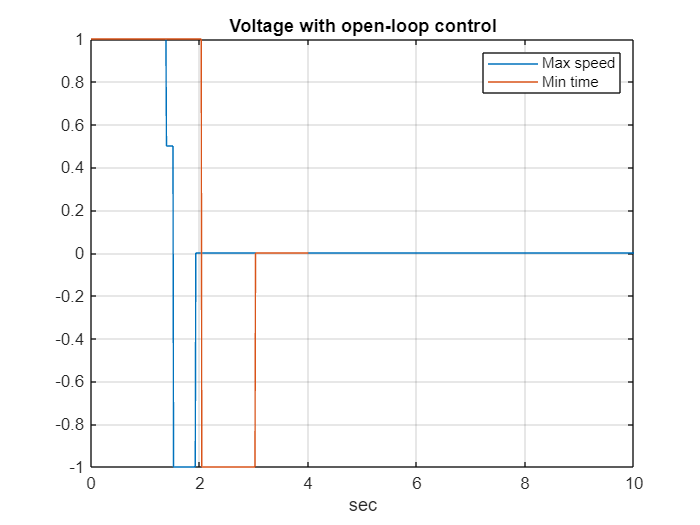

plot(ttnew,uunew,tt,uu); grid
title('Voltage with open-loop control')
legend('Max speed','Min time')
xlabel('sec')

### 2.4 Closed-loop control (unconstrained)

An alternative is to embed a sensor which detects the actual angle and uses this to manipulate the voltage to the servo directly. For example a law of the form:

$U\left(s\right)=M\left(s\right)\left\lbrack \theta_d -\theta \right\rbrack$  where $\theta_d$ is the target.

Given the system model already includes an integrator, a proportional, PD or lead type of compensator would be suitable. For simplicitly again (compensator design is not the main purpose of this resource) use the following (ideally this would change with the load).


$$M\left(s\right)=2\frac{s+1}{s+2}$$


Typical behaviour for a desired angle change of 30 degrees is given in the following figure. Readers may note that the transient input is  over 1 which we will consider lower down as this is not allowed in practice.

disp('Section 2.3 below')

Section 2.3 below


disp(' ');

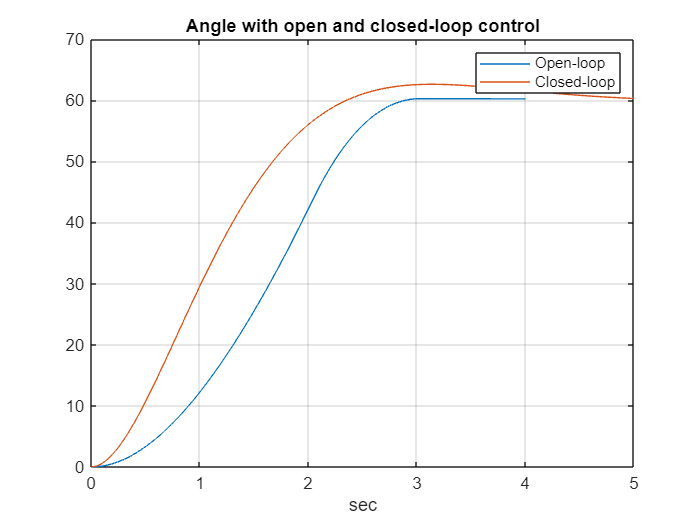

G=tf(1,[1 1 0]);
M = tf(2*[1 1],[1 2]);
Gy=feedback(G*M,1);
Gu=feedback(M,G);
[yc,tc]=step(Gy,5);
uc = step(Gu,tc);
R=target;  Rrad = R*pi/180;
plot(tt,y*180/pi,tc,yc*R); grid;title('Angle with open and closed-loop control'); xlabel('sec')
legend('Open-loop','Closed-loop')

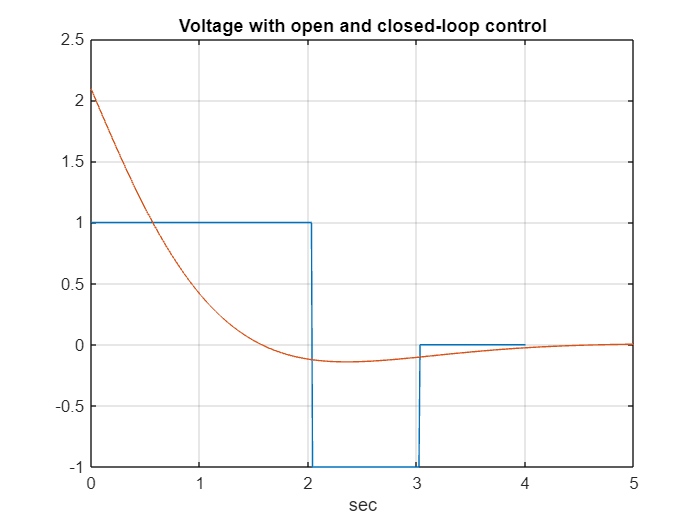

plot(tt,uu,tc,uc*Rrad); grid; title('Voltage with open and closed-loop control'); xlabel('sec')

**Remark**: It will be obvious that in this case the closed-loop is far slower than the bang-bang option although the implementation and tuning is far simpler.

**Remark**: A numerical approach is used to determine the dead-beat control signal and as such it will inevitable be only as accurate as the search method use. Users will therefore note that even with a perfect model, the angle may not be achieved precisely.

## 3. Introducing an authentic scenario

In order to introduce the sorts of uncertainty present in real implementations, it is easier to build the simulation model using simulink. This section focuses on the simulink model and how uncertainty and input limits are embedded within this. See file: ***open_vs_closed_simulink_control101.mlx***

### 3.1 Load and angle changes for minimum time control

The model changes depending on the load and thus the solutions of section 2.1 are needed for multiple loads and multiple angles. These solutions will be stored in a lookup table. The different scenarios correspond to:


$$T=1,2,2\ldotp 5,\;\;\;\vartheta_d =30,60,90$$


disp('Section 3.1 below: Proposed dead-beat voltage signals')

Section 3.1 below: Proposed dead-beat voltage signals


disp(' Loads are: 1, 2, 2.5');

 Loads are: 1, 2, 2.5


t2s = 0.4935

t2s = 1.5098

t2s = 0.7844

t2s = 2.0931

t2s = 0.9004

t2s = 2.3213

t2s = 0.5910

t2s = 2.2296

t2s = 0.9877

t2s = 3.0232

t2s = 1.1503

t2s = 3.3447

t2s = 0.6366

t2s = 2.8436

t2s = 1.1050

t2s = 3.7804

t2s = 1.3016

t2s = 4.1743

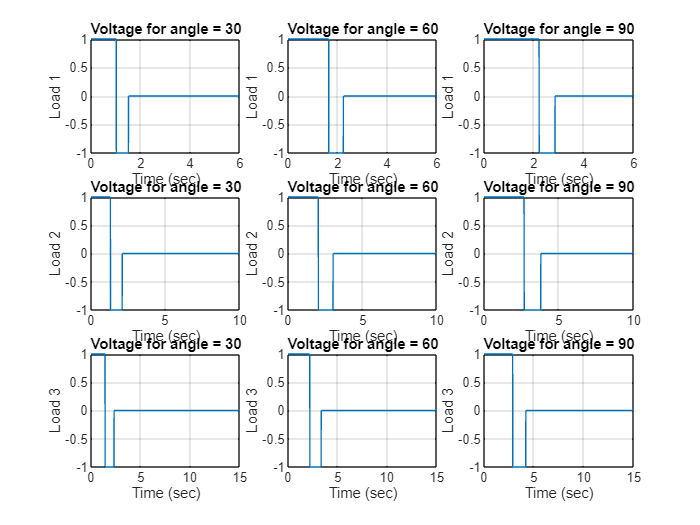

k=0;
clear t1 t2 tt
bang_bang = cell(3,3);  % rows for load, columns for angle
noterms=1001;
tt(1,:) = linspace(0,6,noterms); 
tt(2,:) = linspace(0,10,noterms); 
tt(3,:) = linspace(0,15,noterms); 

u=[ones(1,noterms)];
t1=[];t2=[];bang_bang=cell(3,3);

% Row index is load and column index is the angle
for angle=[30,60,90];
    k=k+1;
    [t1(1,k),t2(1,k)] = findtimes(1,angle,5);
    inputsignal= getbangbang(u,tt(1,:),t1(1,k),t2(1,k));
    bang_bang{1,k} = inputsignal;

    [t1(2,k),t2(2,k)] = findtimes(2,angle,8);
    inputsignal = getbangbang(u,tt(2,:),t1(2,k),t2(2,k));
    bang_bang{2,k} =inputsignal;

    [t1(3,k),t2(3,k)] = findtimes(2.5,angle,12);
    inputsignal = getbangbang(u,tt(3,:),t1(3,k),t2(3,k));
    bang_bang{3,k} =inputsignal;
    for m=1:3;
      kk=(m-1)*3 + (k);
    subplot(3,3,kk);
    plot(tt(m,:),bang_bang{m,k}); grid
    title(['Voltage for angle = ',num2str(angle)])
    xlabel('Time (sec)')
    ylabel(['Load ',num2str(m)])
    end

end

t1

t1 =     1.0163    1.6386    2.2070
    1.3087    2.0355    2.6754
    1.4209    2.1944    2.8727


t2

t2 =     1.5098    2.2296    2.8436
    2.0931    3.0232    3.7804
    2.3213    3.3447    4.1743


The solutions are stored in column index k=1,2,3 for angles 30,60,90 respectively.  Row indices relate to changes in load.

### 3.2 Load and angle changes for maximum speed control

The model changes depending on the load and thus the solutions of section 2.3 are needed for multiple loads and multiple angles. These solutions will be stored in a lookup table. The different scenarios correspond to:


$$T=1,2,2\ldotp 5,\;\;\;\vartheta_d =30,60,90$$


disp('Section 3.2 below: Proposed maximum velocity voltage signals')

Section 3.2 below: Proposed maximum velocity voltage signals


disp(' Loads are: 1, 2, 2.5');

 Loads are: 1, 2, 2.5


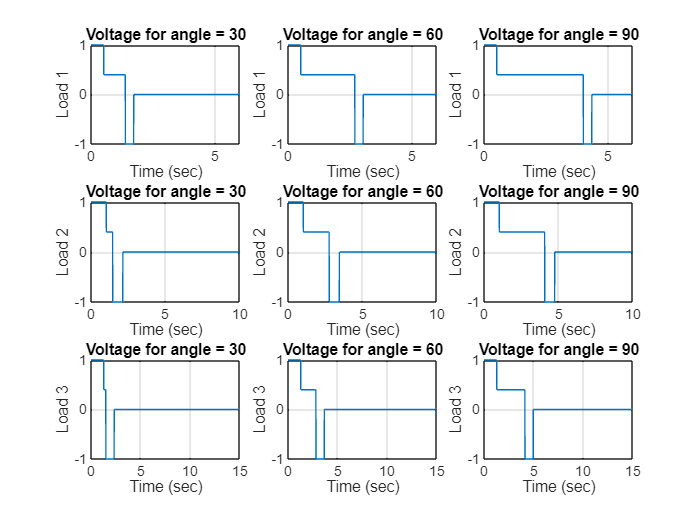

k=0;
wmax=0.4;
max_speed = cell(3,3);  % rows for load, columns for angle
noterms=1001;
ttnew(1,:) = linspace(0,6,noterms); 
ttnew(2,:) = linspace(0,10,noterms); 
ttnew(3,:) = linspace(0,15,noterms); 
figure
% Row index is load and column index is the angle
for angle=[30,60,90];
    k=k+1;
    [uunew] = maxspeedinput(wmax,1,angle*pi/180,ttnew(1,:));
    max_speed{1,k} = uunew;
    [uunew] = maxspeedinput(wmax,2,angle*pi/180,ttnew(2,:));
    max_speed{2,k} = uunew;
    [uunew] = maxspeedinput(wmax,2.5,angle*pi/180,ttnew(3,:));
    max_speed{3,k} = uunew;

    for m=1:3;
      kk=(m-1)*3 + (k);
    subplot(3,3,kk);
    plot(ttnew(m,:),max_speed{m,k}); grid
    title(['Voltage for angle = ',num2str(angle)])
    xlabel('Time (sec)')
    ylabel(['Load ',num2str(m)])
    end

end

### 3.3. Simulink model and uncertainty

First we should re-emphasise that the solutions of sections 3.1 and 3.2 assume precise implementation, including the timings. In reality the computation of the timings will only be accurate to a few decimal places and the implementation will be similarly approximate. Thus the actual arm movement, even with a perfect model, will not be precisely what was planned.

The model has been given as a simple transfer function which, in practice will have different parameters from those given:


$$T=T_{\textrm{mean}} +\delta T;K=K_{\textrm{mean}} +\delta K;\;U=U_{\textrm{expected}} +\delta U$$


The deviations could be considered to be zero-mean random variables; these change with each different simulation run but are fixed within any single simulation. Hence, before the simulation is started, the simulink model will pull in the current active values. Here a simple fixed choice is used.

It is clear that the open-loop approach is prone to errors, that is the end position will often not be what is required. Any offset will cause the arm to not be aligned with the tray and thus either pick up or delivery will be impaired.

disp('Section 3.3 below: Open-loop behaviour with and without uncertainty')

Section 3.3 below: Open-loop behaviour with and without uncertainty


disp(' ');

% Set up parameters for the simulink file
loadchoice=1; num =1; den = [1 1 0]; num2 = 1.1;den2 = [1.1 1 0]; endtime = tt(1,end);  % default model T=1, K=1;
loadchoice=2; num =1; den = [2 1 0]; num2 = 1.1;den2 = [1.9 1 0]; endtime = tt(2,end);   % default model T=2, K=1;
%loadchoice=3; num =1; den = [2.5 1 0]; num2 = 0.9; den2 = [2.4 1 0]; endtime = tt(3,end);  % default model T=2.5, K=1;
Knum=[2 2]; Kden = [1 2]; M = tf(Knum,Kden); % compensator
target=[30,60,90]*pi/180;
   

disp(['Simulations with and without parameter errors and simulink for load ',num2str(loadchoice)])

Simulations with and without parameter errors and simulink for load 2


disp('Targets of 30, 60 and 90')

Targets of 30, 60 and 90


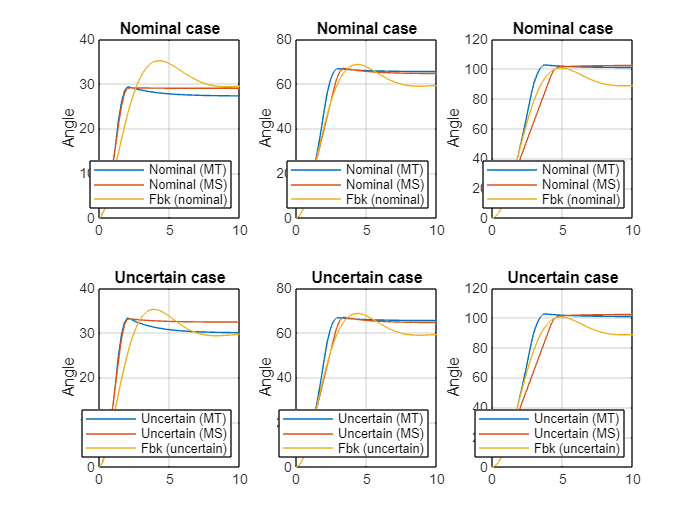


G=tf(num,den);G2 = tf(num2,den2);
storesimulinkoutputs=cell(1,3);
storesimulinkoutputs1=cell(1,3);
storesimulinkoutputsnew=cell(1,3);
storesimulinkoutputs1new=cell(1,3);
storesimulinkoutputsfbk=cell(1,3);
storesimulinkoutputsfbk1=cell(1,3);
figure

for k=1:3;
    kk=(k-1)*2+1;
   
    % min time option
   
    min_time_signal.time=[tt(loadchoice,:)'];   % minimum time  signal
    min_time_signal.signals.values=[bang_bang{loadchoice,k}'] ;   
    var.min_time_signal.dimensions=[1];
    max_speed_signal.time=[ttnew(loadchoice,:)'];   % bang bang signal
    max_speed_signal.signals.values=[max_speed{loadchoice,k}'] ;   % 30 degrees and no load
    var.max_speed_signal.dimensions=[1];
    target_signal.time=[tt(loadchoice,:)'];
    target_signal.signals.values=[target(k)*ones(size(tt(loadchoice,:)))'] ;  

    % nominal case
    num=num; den =den;
    out = sim('open_vs_closed_simulink_control101.slx');  % simulink responses
    storesimulinkoutputs{k} = out.min_time_out;
    storesimulinkoutputsnew{k} = out.max_speed_out;
    storesimulinkoutputsfbk{k} = out.closedloopout;
    
    % Uncertain case
    num=num2; den =den2;
    out = sim('open_vs_closed_simulink_control101.slx');  % simulink responses
    storesimulinkoutputs1{k} = out.min_time_out;
    storesimulinkoutputs1new{k} = out.max_speed_out;
    storesimulinkoutputsfbk1{k} = out.closedloopout;
    

    % max speed option (Simple transfer function simulation)
    % [ylin]=lsim(G,bang_bang{loadchoice,k},tt(loadchoice,:));
    % [ylinnew]=lsim(G,max_speed{loadchoice,k},ttnew(loadchoice,:));
   

    % plotting: Nominal then uncertain
subplot(2,3,k);
plot(storesimulinkoutputs{k}.Time,storesimulinkoutputs{k}.Data(:,2)*180/pi,...
    storesimulinkoutputsnew{k}.Time,storesimulinkoutputsnew{k}.Data(:,2)*180/pi,...
    storesimulinkoutputsfbk{k}.Time,storesimulinkoutputsfbk{k}.Data(:,2)*180/pi)
    title('Nominal case')
legend('Nominal (MT)','Nominal (MS)','Fbk (nominal)','Location','southeast')
ylabel('Angle')
grid
    
subplot(2,3,k+3);
plot(storesimulinkoutputs1{k}.Time,storesimulinkoutputs1{k}.Data(:,2)*180/pi,...
    storesimulinkoutputs1new{k}.Time,storesimulinkoutputs1new{k}.Data(:,2)*180/pi, ...
   storesimulinkoutputsfbk1{k}.Time,storesimulinkoutputsfbk1{k}.Data(:,2)*180/pi)
    grid
title('Uncertain case')
legend('Uncertain (MT)','Uncertain (MS)','Fbk (uncertain)','Location','southeast')
ylabel('Angle')
end

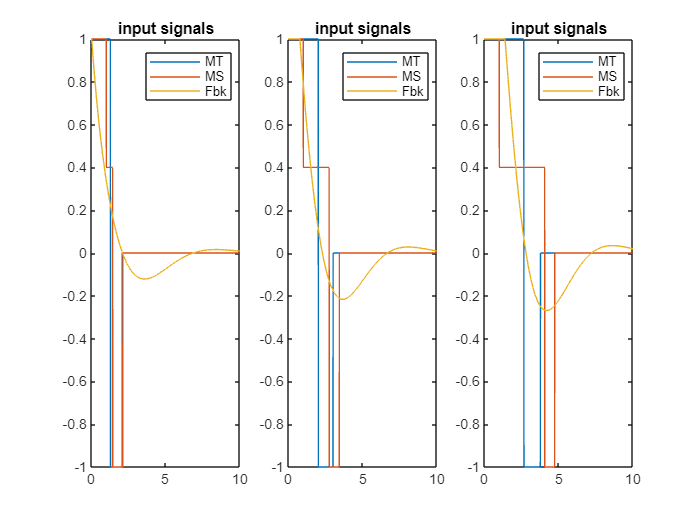


% Input signal plotting
figure
for k=1:3
subplot(1,3,k)
plot(tt(loadchoice,:)',bang_bang{loadchoice,k}',...
    ttnew(loadchoice,:)',max_speed{loadchoice,k}', ...
   storesimulinkoutputsfbk{k}.Time,storesimulinkoutputsfbk{k}.Data(:,1))
title('input signals')
legend('MT','MS','Fbk')
end

### 3.4. Feedback proposals

Obviously errors can accumulate as the arm moves multiple times and thus some re-centering method would be essential in practice. In essence this is an argument for feedback, the introduction of some sensing of position and control action dependent upon that measurement (Figure 1.). This section shows how, albeit slower, a simple feedback law improves the tracking performance enormously. Section 3.3 includes these, but with input constraints included.

disp(['Section 3.4 below: Closed-loop control with load ',num2str(loadchoice)])

Section 3.4 below: Closed-loop control with load 2


disp(' ');

disp('Targets of 30, 60 and 90')

Targets of 30, 60 and 90


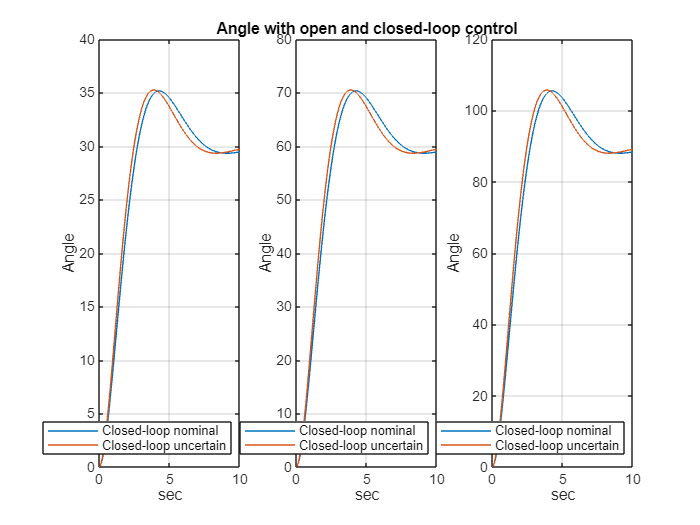

target=[30,60,90];
figure

for k=1:3;
    kk=(k-1)*2+1;

    % Linear closed-loop
    Gy=feedback(G*M,1);
    Gu=feedback(M,G);
    Gy2=feedback(G2*M,1); % with uncertainty
    Gu2=feedback(M,G2);
    [yc,tc]=step(Gy,endtime(end));            % closed-loop
    uc = step(Gu,tc);
    [yc2]=step(Gy2,tc);            % closed-loop
    uc2 = step(Gu2,tc);
    Rrad = target(k);
   

    subplot(1,3,k);
    plot(tc,yc*Rrad,tc,yc2*Rrad)
    if k==2;title('Angle with open and closed-loop control'); end
    xlabel('sec')
    legend('Closed-loop nominal','Closed-loop uncertain','Location','southeast')
    ylabel('Angle')
    grid
end

## 4 Using the app interface

The interface is shown in Figure 4.1 below. The user has relatively limited choices:

In the yellow box: 

- Choose the load magnitude

- Choose which strategy to animate (appears in right hand figure).

In the green box:

- Choose angle move desired from 30, 60, 90 or a short sequence of moves.

In the orange box

- Choose the uncertainty in the load magnitude and motor gain.

Once choices are made, press the pink button to see the responses.

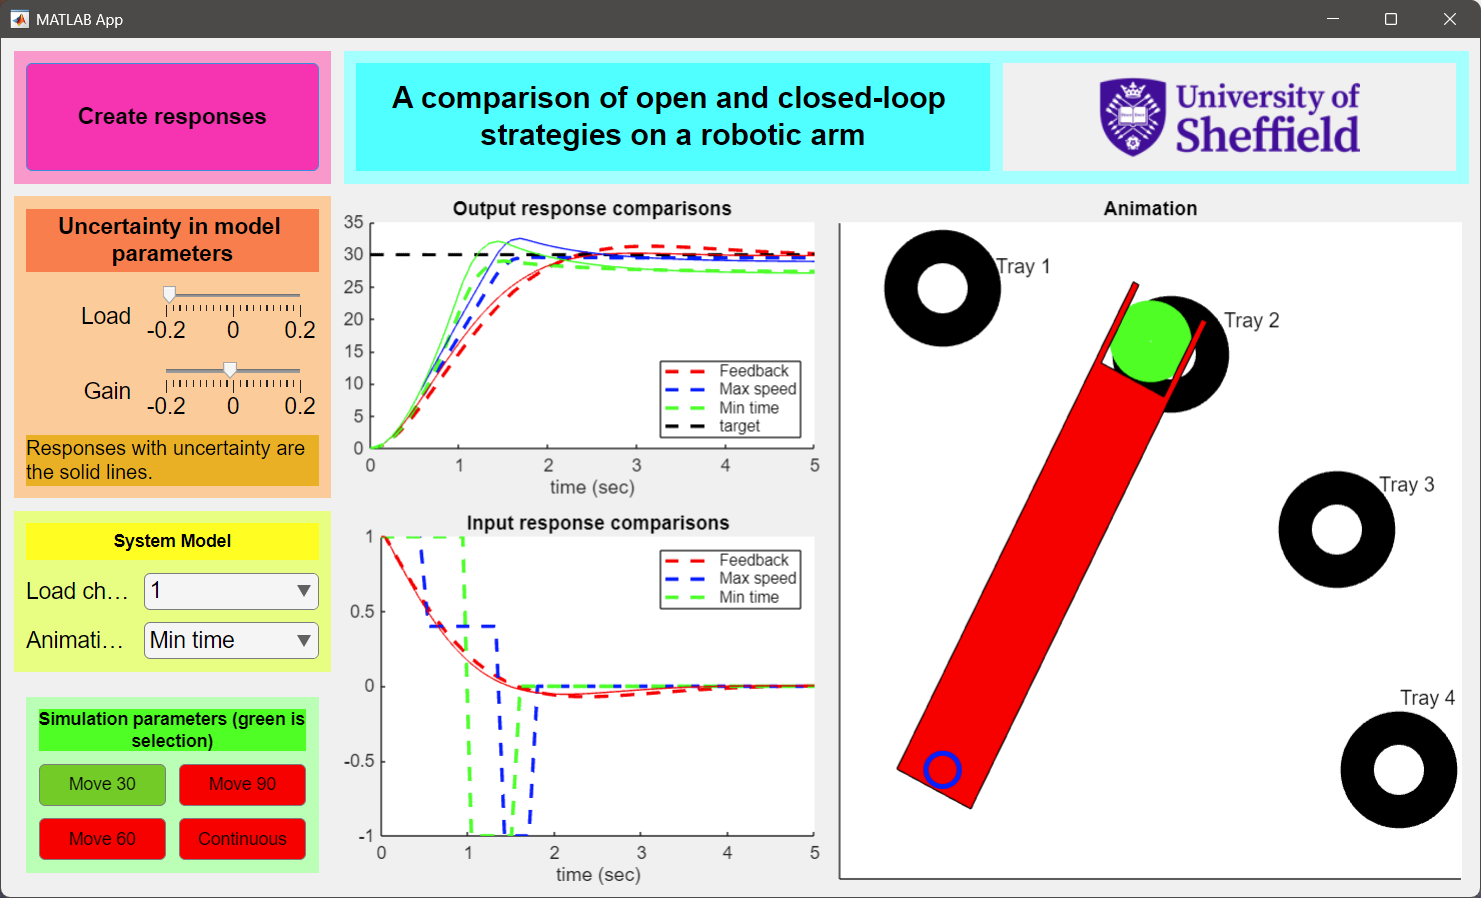

Figure 4.1. *App interface*

- It will be evident that feedback option is slower, but reliable; also the tuning could be improved. 

- The open-loop options lead to steady-state errors which can become critical failure points for some uncertainty and ndeed continuous moves.

**Remark**: The input is capped at plus or minus one for all the simulations.

## 5. Appendix: Subfunction to find the switch times for bang bang control

function [t1s,t2s] = findtimes(load,angle,endtime)

T=load;

t1=linspace(0.1,endtime,1001);
for k=1:length(t1);   
        alpha =exp(-t1(k)/T);
        w = 1-alpha;
        t2 = T*log(1+w);  % in fact t2-t1
        beta = exp(-t2/T);
        gamma = t2;
        delta(k)=t1(k)-T*(1-alpha)-(gamma - T*(1-beta)) +T*(1-beta)*(1-alpha);   
end

[val,k]=min(abs(delta*180/pi-angle)); % index closest to required angle
t1s = t1(k);  %% angle degrees
alpha =exp(-t1s/T); 
t2s = T*log(2-alpha)
t2s=t2s+t1s

end

% Find input signal for min time changes
function uu=getbangbang(u,tt,t1s,t2s)

ufalse =le(tt,t1s);
ufalse2 =le(tt,t2s);
u1=-u.*ufalse2;
u2 =u.*ufalse;
uu=2*u2+u1;

end

% Find the input signal for maximum speed movements
function [uu] = maxspeedinput(wmax, load,angle,tt)

T=load;
u=[ones(1,length(tt))];
tau1 = -T*log(1-wmax);
tau3 = T*log(1+wmax);
tau2 = (angle +tau3 - tau1)/wmax;
ufalse =le(tt,tau1);
ufalse2 =ge(tt,tau1+tau2);
ufalse3 =ge(tt,tau3+tau1+tau2);
uc1 = ge(tt,tau1).*u;
uc2 = ge(tt,tau1+tau2).*u;
u2=-u.*ufalse2;
u1 =u.*ufalse;
u3=u.*ufalse3;
uu=u2+u1+u3 +(uc1-uc2)*wmax;
end